clc, clear all

[x]=xlsread('C:\Users\yzh74\Optical Tweezers Results Analysis\trap_position.csv') 

x =    23.6116
   23.6115
   23.6117
   23.6114
   23.6115
   23.6117
   23.6115
   23.6114
   23.6115
   23.6111


[y]=xlsread('C:\Users\yzh74\Optical Tweezers Results Analysis\force.csv') 

y =     0.3131
    0.1154
    0.1814
   -0.0604
   -0.2647
    0.1492
    0.1297
   -0.2481
   -0.4853
   -0.1871



% Creating spline function to represent F-D curve
xx=linspace(x(1),x(max),100);
yy=spline(x,-y,xx);

% Calculating energy profile from the integral of the force-distance curve
G1 = []


G1 =

     []



for i = 1:100
    u = xx(i)
    G = integral(@(xx)spline(x,-y,xx),xx(1),u,'ArrayValued',true)
    G1 = [G1,G]
end

函数或变量 'xx' 无法识别。

disp(G1)

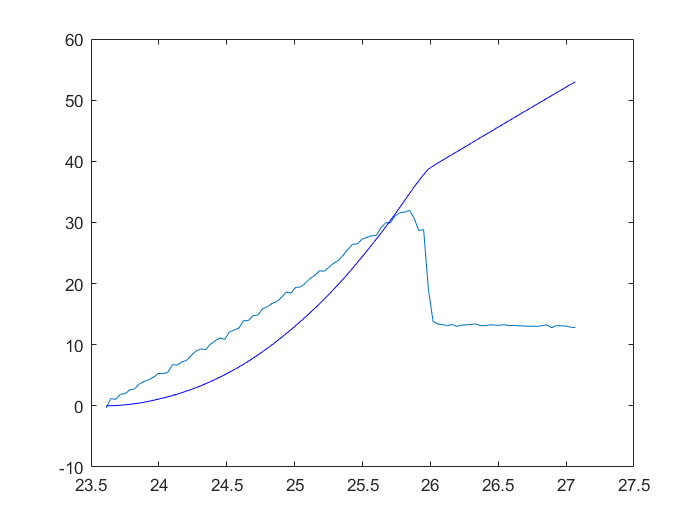

plot(xx,yy)
hold on
plot(xx,G1,"b-")
hold off